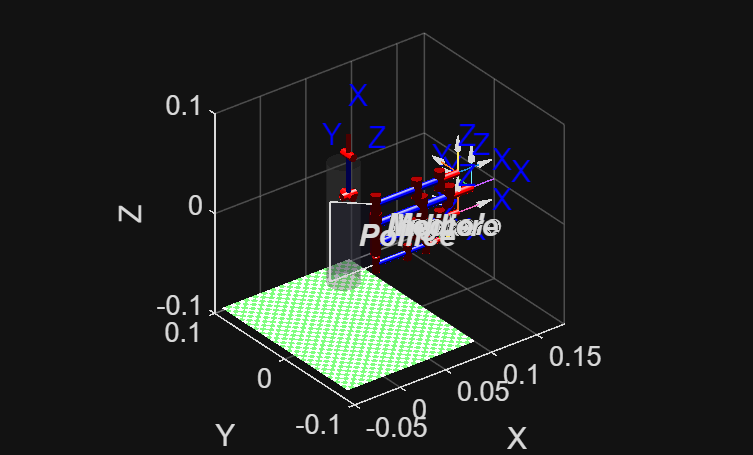

% 1 Definizioni link,oggetti,gravità (diretta come - y),cilindro e palmo
close all; clear; clc;

L_ind = [ Link([0 0 0.045 0]),Link([0 0 0.025 0]), Link([0 0 0.020 0]) ];
L_med = [ Link([0 0 0.050 0]), Link([0 0 0.030 0]),Link([0 0 0.025 0]) ];
L_anu = [ Link([0 0 0.045 0]),Link([0 0 0.025 0]),Link([0 0 0.020 0]) ];
L_mig = [ Link([0 0 0.035 0]),Link([0 0 0.020 0]),Link([0 0 0.015 0]) ];
L_pol = [ Link([0 0 0 pi/2]),Link([0 0 0.040 0]),Link([0 0 0.030 0]) ];

indice  = SerialLink(L_ind, 'name', 'Indice');
medio   = SerialLink(L_med, 'name', 'Medio');
anulare = SerialLink(L_anu, 'name', 'Anulare');
mignolo = SerialLink(L_mig, 'name', 'Mignolo');
pollice = SerialLink(L_pol, 'name', 'Pollice');

L_palmo = 0.05;
indice.base  = transl(L_palmo, 0, 0.02);
medio.base   = transl(L_palmo, 0, 0);
anulare.base = transl(L_palmo, 0, -0.02);
mignolo.base = transl(L_palmo, 0, -0.04);
pollice.base = transl(0.02, 0, 0.04) * troty(-pi/2);

% Gravità
vettore_g = [0; 9.81; 0]; % non mettere segno meno, già incluso nella logica
indice.gravity = vettore_g;
medio.gravity = vettore_g;
anulare.gravity = vettore_g;
mignolo.gravity = vettore_g;
pollice.gravity = vettore_g;

% Cilindro
r_cil = 0.015;          
pos_cil = [0.03, 0.02, 0]; 
h_cil = 0.12;

% Dsiegno della configurazione iniziale
figure(1); hold on; grid on;
axis([-0.05 0.18 -0.10 0.10 -0.10 0.10]); 
view(125, 25);
xlabel('X'); ylabel('Y'); zlabel('Z');

[xc, yc, zc] = cylinder(r_cil, 50);
zc = zc * h_cil - (h_cil/2);
surf(xc + pos_cil(1), yc + pos_cil(2), zc + pos_cil(3), 'FaceColor', [0.8 0.8 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

palm_x = [0 0.05 0.05 0]; palm_z = [-0.04 -0.04 0.02 0.04];
patch(palm_x, zeros(size(palm_x)), palm_z, 'b', 'FaceAlpha', 0.1);

q0 = [0 0 0];  % cond iniziali pos
qd0 = [0 0 0]; % condizioni iniziali vel
indice.plot(q0,  'noshadow', 'nobase');
medio.plot(q0,   'noshadow', 'nobase');
anulare.plot(q0, 'noshadow', 'nobase');
mignolo.plot(q0, 'noshadow', 'nobase');
pollice.plot(q0, 'noshadow', 'nobase', 'jointcolor', 'r');

% 2 Calcolo punti di contattatto dita lunghe con ottimizzazione
f_vincolo = @(s) [s, 1.2*s, 0.8*s]; 
obiettivo_dita = @(q, robot, pos_c, r_c) abs(norm(robot.fkine(q).t(1:2) - pos_c(1:2)') - r_c);

dita_lunghe = {indice, medio, anulare, mignolo};
nomi_lunghe = {'Indice', 'Medio', 'Anulare', 'Mignolo'};
q_contatto = cell(1, 5);

fprintf('\n Posizioni target \n');


 Posizioni target 


for i = 1:4
    s_opt = fminbnd(@(s) obiettivo_dita(f_vincolo(s), dita_lunghe{i}, pos_cil, r_cil), 0, pi/2); 
    q_contatto{i} = f_vincolo(s_opt); 
    fprintf('%s -> Target trovato con s = %.2f rad\n', nomi_lunghe{i}, s_opt);    
end

Indice -> Target trovato con s = 1.34 rad
Medio -> Target trovato con s = 1.43 rad
Anulare -> Target trovato con s = 1.34 rad
Mignolo -> Target trovato con s = 1.21 rad


% Calcolo punto di contatto pollice con dinamica inversa 
T_pol_target = transl(pos_cil(1), pos_cil(2) + r_cil, 0.04); 
q_contatto{5} = pollice.ikine(T_pol_target, 'mask', [1 1 1 0 0 0]);
q_p = q_contatto{5};
fprintf('Pollice (IKINE) -> q1: %.4f, q2: %.4f, q3: %.4f\n', q_p(1), q_p(2), q_p(3));

Pollice (IKINE) -> q1: 1.5708, q2: 0.5235, q3: -2.0824


% 3 Aggiungo dinamica,calcolo traiettoria e simulazione
indice  = add_dynamic_props(indice);
medio   = add_dynamic_props(medio);
anulare = add_dynamic_props(anulare);
mignolo = add_dynamic_props(mignolo);
pollice = add_dynamic_props(pollice);

dita = {indice, medio, anulare, mignolo, pollice};
nomi = {'Indice', 'Medio', 'Anulare', 'Mignolo', 'Pollice'};

T_sim = 2.0;   % faccio durare la simulazione totale 2 secondi    
dt = 0.001;        
t = 0:dt:T_sim;
steps = length(t);

% Guadagni PD per il tracciamento 
Kp = 0.5;  
Kd = 0.1;   

% Inizializzazione per posizione, velocità e accelerazione
q_hist     = cell(1, 5); 
qd_hist    = cell(1, 5); 
qddot_hist = cell(1, 5); 

for i=1:5
    q_hist{i}     = zeros(steps, 3); 
    qd_hist{i}    = zeros(steps, 3);
    qddot_hist{i} = zeros(steps, 3);
end


%  traiettoria con polinomio di quinto grado
t_traj = 0:dt:1.5; % traiettoria di 1.5 secondi
Q_des = cell(1, 5); 
Qd_des = cell(1, 5);

for i = 1:5
    
    [Q_des{i}, Qd_des{i}, ~] = jtraj([0 0 0], q_contatto{i}, t_traj);
end


for i = 1:5
    fprintf('Simulazione dito %d in corso...\n', i);
    robot = dita{i};
    ctrl_handle = @(robot, t, q, qd) control_law(robot, t, q, qd, t_traj, Q_des{i}, Qd_des{i}, Kp, Kd);
    [t_out, q_out, qd_out] = robot.fdyn(T_sim, ctrl_handle, q0, qd0);

    t_out = t_out(:); 
    [t_out_uniq, idx_uniq] = unique(t_out);
    q_out_uniq  = q_out(idx_uniq, :);
    qd_out_uniq = qd_out(idx_uniq, :);

    qddot_raw = zeros(length(t_out_uniq), 3);

    for k = 1:length(t_out_uniq)
        coppia_raw = control_law(robot, t_out_uniq(k), q_out_uniq(k,:), qd_out_uniq(k,:), ...
                             t_traj, Q_des{i}, Qd_des{i}, Kp, Kd);
     
        qddot_raw(k,:) = robot.accel(q_out_uniq(k,:), qd_out_uniq(k,:), coppia_raw)';
     
    end

    q_hist{i}     = interp1(t_out_uniq, q_out_uniq, t, 'pchip', 'extrap');
    qd_hist{i}    = interp1(t_out_uniq, qd_out_uniq, t, 'pchip', 'extrap');
    qddot_hist{i} = interp1(t_out_uniq, qddot_raw, t, 'pchip', 'extrap');
    
end

Simulazione dito 1 in corso...
Simulazione dito 2 in corso...
Simulazione dito 3 in corso...
Simulazione dito 4 in corso...
Simulazione dito 5 in corso...



fprintf('Simulazione completata con fdyn.\n');

Simulazione completata con fdyn.


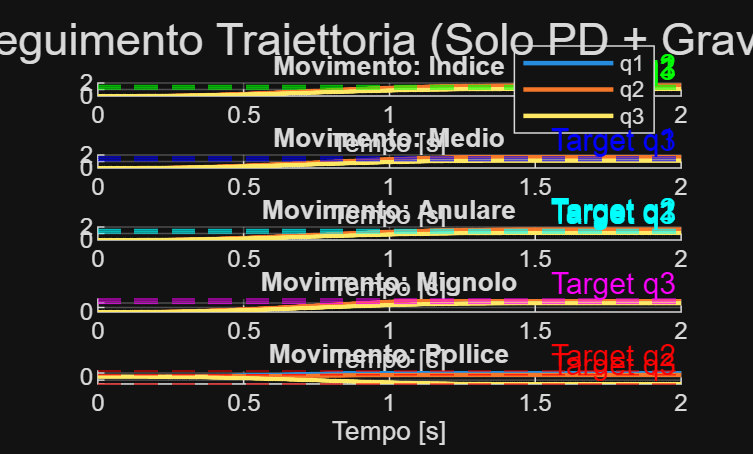


% 4 VISUALIZZAZIONE RISULTATI 
figure(2); clf;
sgtitle('Inseguimento Traiettoria (Solo PD + Gravità)');

colori = {'g','b','c','m', 'r'};

for j = 1:5 
    colore = colori{j};
    
    subplot(5,1,j); hold on; grid on;
    plot(t, q_hist{j}, 'LineWidth', 1.5);
    
    final_target = q_contatto{j};
    yline(final_target(1), ['--' colore], 'Target q1');
    yline(final_target(2), ['--' colore], 'Target q2');
    yline(final_target(3), ['--' colore], 'Target q3');
    
    title(['Movimento: ' nomi{j}]);
    if j==1
     legend('q1', 'q2', 'q3', 'Location', 'Best');
    end
    xlabel('Tempo [s]'); ylabel('Radianti');
end

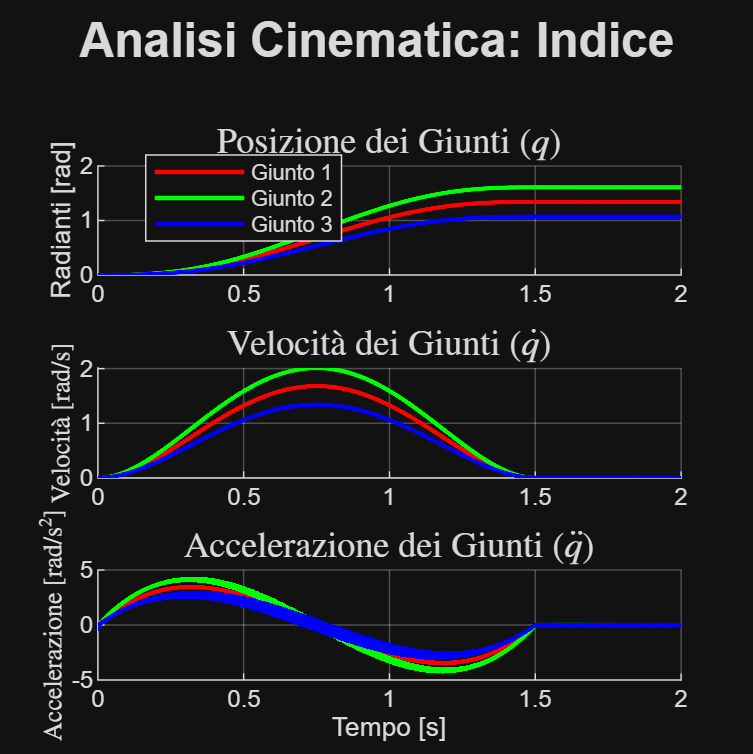

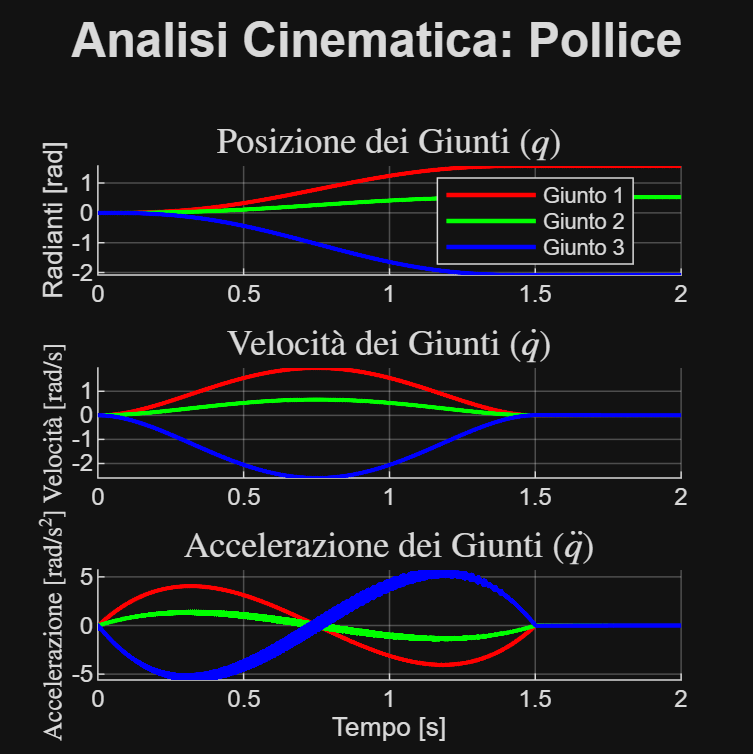



% Grafici pos,vel,acc(Indice e Pollice)

dita_da_analizzare = [1, 5]; 
for idx = dita_da_analizzare
    figure('Name', ['Analisi Dinamica - ' nomi{idx}], 'Position', [200, 100, 800, 800]);
    sgtitle(['Analisi Cinematica: ' nomi{idx}], 'FontSize', 16, 'FontWeight', 'bold');
    
    % GRAFICO POSIZIONE (q) 
    subplot(3, 1, 1); hold on; grid on;
    plot(t, q_hist{idx}(:, 1), 'r', 'LineWidth', 1.5);
    plot(t, q_hist{idx}(:, 2), 'g', 'LineWidth', 1.5);
    plot(t, q_hist{idx}(:, 3), 'b', 'LineWidth', 1.5);
    title('Posizione dei Giunti ($q$)', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('Radianti [rad]');
    legend('Giunto 1', 'Giunto 2', 'Giunto 3', 'Location', 'Best');
    
    % GRAFICO VELOCITÀ (q dot)
    subplot(3, 1, 2); hold on; grid on;
    plot(t, qd_hist{idx}(:, 1), 'r', 'LineWidth', 1.5);
    plot(t, qd_hist{idx}(:, 2), 'g', 'LineWidth', 1.5);
    plot(t, qd_hist{idx}(:, 3), 'b', 'LineWidth', 1.5);
    title('Velocit\`a dei Giunti ($\dot{q}$)', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('Velocit\`a [rad/s]', 'Interpreter', 'latex');
    
    % GRAFICO ACCELERAZIONE (q ddot)
    subplot(3, 1, 3); hold on; grid on;
    plot(t, qddot_hist{idx}(:, 1), 'r', 'LineWidth', 1.5);
    plot(t, qddot_hist{idx}(:, 2), 'g', 'LineWidth', 1.5);
    plot(t, qddot_hist{idx}(:, 3), 'b', 'LineWidth', 1.5);
    title('Accelerazione dei Giunti ($\ddot{q}$)', 'Interpreter', 'latex', 'FontSize', 12);
    xlabel('Tempo [s]');
    ylabel('Accelerazione [rad/s$^2$]', 'Interpreter', 'latex');

  
end

% Funzione per aggiungere la dinamica alle dita 
function robot = add_dynamic_props(robot)
    rho = 4000; 
    for j = 1:robot.n 
        L = robot.links(j);
        a = L.a; 
        if a == 0, a = 0.001; end 
        r_p = 0.005; 
        volume = pi * r_p^2 * a;
        massa = rho * volume;
        L.m = massa; 
        L.r = [a/2, 0, 0]; 
        Ixx = 0.5 * massa * r_p^2; 
        Iyy = (1/12) * massa * (3*r_p^2 + a^2);
        Izz = Iyy;
        L.I = [Ixx, Iyy, Izz, 0, 0, 0];
        L.G = 1;      
        L.Jm = 1e-4;      
        L.B = 1e-4;       
        L.Tc = [1e-4, 1e-4]; 
    end
    robot = SerialLink(robot); 
end

%Q riferimenti traiettoria
function tau = control_law(robot, t, q, qd, t_traj, Q_des, Qd_des, Kp, Kd)
    q = q(:)';  
    qd = qd(:)';

    % Interpolazione per trovare il punto desiderato all'istante t
    if t <= t_traj(end)
        q_d  = interp1(t_traj, Q_des, t, 'spline'); % anche 'linear' va bene
        qd_d = interp1(t_traj, Qd_des, t, 'spline');
    else
        q_d  = Q_des(end, :);
        qd_d = [0, 0, 0]; 
    end
    
    % Calcolo Errore
    e  = q_d - q;
    ed = qd_d - qd;

    % Compensazione di Gravità + Controllo PD
    G = robot.gravload(q);
    tau = (Kp * e + Kd * ed) + G;
end